MECE6397: Learning-Based Control

# Homework 2: Gain Scheduling of Autopilot

Instructor: Marzia Cescon

**Gain scheduling** is a feedback control system in which the controller parameters are adjusted based on measurements of the operating conditions of the process, in a preprogrammed way, by using feedforward compensation. It is often a good way to compensate for variations in process dynamics when auxiliary variables that correlate well with such variations are found. Figure 1 below shows the block diagram of a system with gain scheduling. For more information about gain scheduling, implementations and minimization of the negative effects of switching gains, check the video [What Is Gain Scheduling? | Control Systems in Practice](https://www.mathworks.com/videos/control-systems-in-practice-part-2-what-is-gain-scheduling-1535711972066.html).

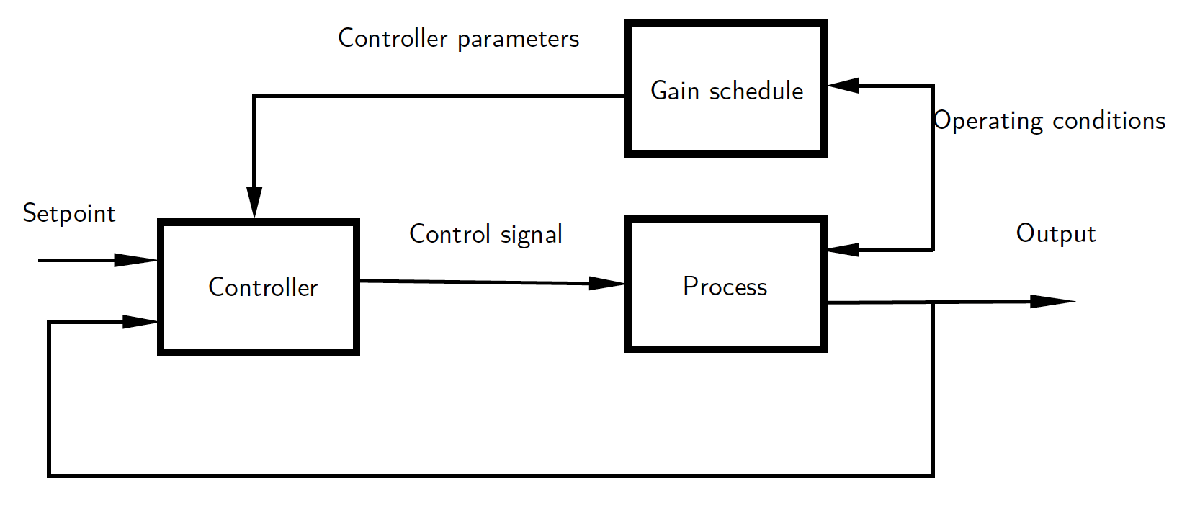

*Figure 1. Block diagram of a system with gain scheduling.*

The concept of gain scheduling originated in connection with the development of flight control systems. This homework provides hands-on experience on how to generate smooth gain schedules for a three-loop autopilot. 

## 1. Airframe Model and Three-Loop Autopilot

This example uses a three-degree-of-freedom (3-DoF) model of the pitch axis dynamics of an airframe. The states are the Earth coordinates ($X_e ,Z_e$), the body coordinates ($u,v$), the pitch angle $\theta$, and the pitch rate $q=\dot{\;\theta }$. The relationship between the inertial and body frames, the flight path angle $\gamma$, the incidence angle $\alpha$, and the pitch angle $\theta$ are shown in Fig. 2.

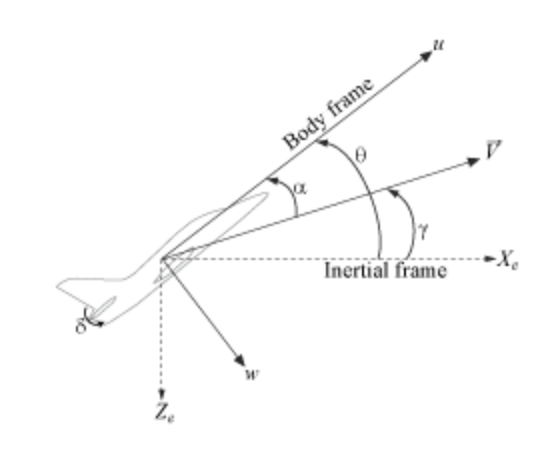

*Figure 2. Coordinate systems for an airframe.*

We use a classic three-loop autopilot structure to control the flight path angle $\gamma$. This autopilot adjusts the flight path by delivering adequate bursts of normal acceleration $a_z$, which is the acceleration along $w$. In turn, normal acceleration is produced by adjusting the elevator deflection $\delta$ to cause pitching and vary the amount of lift. The autopilot uses Proportional-Integral (PI) control in the pitch rate loop $q$ and proportional control in the $z_z$ and $\gamma$ loops. Figure 3 illustrates the Simulink model of the closed-loop system (airframe and autopilot). 

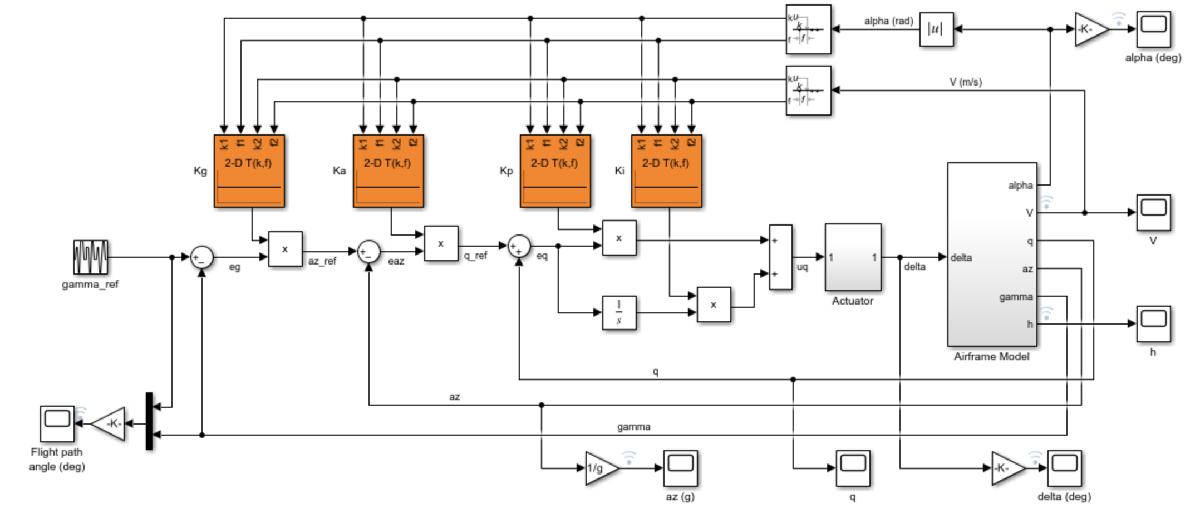

*Figure 3. Simulink model of airframe and autopilot.*

Open `GainScheduleModel.slx`:

open_system('GSmodel')

**Task 1.** Compare the Simulink model of the closed-loop system with the general gain scheduling block diagram in Fig. 1. Can you identify setpoint, control signal, process, output, operating conditions, gain schedule and controller parameters?

Setpoint = "Select one of the following"
Control_signal = "Select one of the following"
Process = "Select one of the following"
Output = "Select one of the following"
Operating_conditions = "Select one of the following"
Gain_schedule = "Select one of the following"
Controller_parameters = "Select one of the following"

## 2. Autopilot Gain Scheduling

The airframe dynamics is nonlinear and the aerodynamic forces and moments depend on incidence $\alpha$ [deg] and speed $V$[m/s]. To obtain suitable performance throughout the $\left(\alpha ,V\right)\;$ flight envelope, the autopilot gains must be adjusted as a function of $\alpha$ and $V$ to compensate for changes in plant dynamics. This adjustment process is called *gain scheduling* and $\left(\alpha ,V\right)$ are called the scheduling variables. In the Simulink model, gain schedules are implemented as lookup tables driven by measurements of $\alpha$ and $V$.

The idea is to compute linear approximations of the plant at various operating conditions, tune the controller gains at each operating condition, and swap gains as a function of operating condition during operation. Conventional gain scheduling involves the following major steps:

- Trim and linearize the plant at each operating condition.

- Tune the controller gains for the linearized dynamics at each operating condition.

- Reconcile the gain values to provide smooth transition between operating conditions.

In this example, we combine steps 2 and 3 by parameterizing the autopilot gains as first-order polynomials in $\left(\alpha ,V\right)$ and directly tuning the polynomial coefficients for the entire flight envelope. This approach eliminates step 3 and guarantees smooth gain variations as a function of the scheduling variables. Moreover, the gain schedule coefficients can be automatically tuned with the command systune.

## 3. Trimming and Linearization

Assume that the incidence $\alpha$ varies between -20 and 20 degrees and that the speed $V$ varies between 700 and 1400 [m/s]. When neglecting gravity, the airframe dynamics are symmetric in $\alpha$. 

**Task 2.** Consider only positive values of $\alpha$ and use a 5-by-9 grid of linearly spaced $\left(\alpha ,V\right)$ pairs to cover the flight envelope. Hint: Use `ndgrid` and `linspace`.

nA = 5;  % number of alpha values
nV = 9;  % number of V values

[alpha,V] = ...; % Complete the missing code.

figure 
plot(alpha, V,'o')
xlabel('\alpha [rad]')
ylabel('V [m/s]')

For each flight condition $\left(\alpha ,V\right)$, linearize the airframe dynamics at trim (zero normal acceleration and pitching moment). This requires computing the elevator deflection $\delta$ and pitch rate $q$ that result in steady $w$ and $q$. To do this, first isolate the airframe model in a separate Simulink model:

mdl = 'GSmodelTrim';
open_system(mdl)

We use the command operspec to specify the trim condition for each $\left(\alpha ,V\right)$ pair and the command findop to compute the trim values of $\delta$ and $q$. We repeat these steps for the 45 flight conditions $\left(\alpha ,V\right)$.

for ct=1:nA*nV
   alpha_ini = alpha(ct);      % Incidence [rad]
   v_ini = V(ct);              % Speed [m/s]
   
   % Specify trim condition
   opspec(ct) = operspec(mdl);
   % Xe,Ze: known, not steady
   opspec(ct).States(1).Known = [1;1];
   opspec(ct).States(1).SteadyState = [0;0];
   % u,w: known, w steady
   opspec(ct).States(3).Known = [1 1];
   opspec(ct).States(3).SteadyState = [0 1];
   % theta: known, not steady
   opspec(ct).States(2).Known = 1;
   opspec(ct).States(2).SteadyState = 0;
   % q: unknown, steady
   opspec(ct).States(4).Known = 0;
   opspec(ct).States(4).SteadyState = 1;
end
opspec = reshape(opspec,[nA nV]);
Options = findopOptions('DisplayReport','off');
op = findop(mdl,opspec,Options);

**Task 3.** List the obtained trim values of $\delta$ and $q$ corresponding to $\alpha =0\ldotp 2618\ldotp \;$Hint: Compare the plotted flight conditions with `op.` What row corresponds to $\alpha =0\ldotp 2618$?

Finally we linearize the airframe dynamics for the resulting operating points:

G = linearize(mdl,op);
G.u = 'delta';
G.y = {'alpha','V','q','az','gamma','h'};
G.SamplingGrid = struct('alpha',alpha,'V',V);

This process produces a 5-by-9 array of linearized plant models at the 45 flight conditions. The plant dynamics vary substantially across the flight envelope.

**Task 4.** Verify this statement by plotting the Bode diagrams and the singular values for the state-space models corresponding to the 45 flight conditions. Hint: Use `sigma` and `bodemag.`

 
title('Variations in airframe dynamics')
 
title('Magnitude of Bode diagram')

## 4. Tunable gain surface

The autopilot consists of four gains $k_p ,k_i ,k_a ,k_g$ to be scheduled, i.e., adjusted, as a function of the scheduling variables. Practically, this means tuning 88 values in each of the corresponding four lookup tables. Rather than tuning each table entry separately, parameterize the gains as a two-dimensional gain surfaces, for example, surfaces with a simple multi-linear dependence on $\alpha$ and $V$:


$$K\left(\alpha ,V\right)=K_0 +K_1 \alpha +K_2 V+K_3 \alpha V$$


This operation cuts the number of variables from 88 down to 4 for each lookup table. We use the command tunableSurface to parameterize each gain surface:

TuningGrid = struct('alpha',alpha,'V',V);
ShapeFcn = @(alpha,V) [alpha,V,alpha*V];

Kp = tunableSurface('Kp',0.1, TuningGrid,ShapeFcn);
Ki = tunableSurface('Ki',2, TuningGrid,ShapeFcn);
Ka = tunableSurface('Ka',0.001, TuningGrid,ShapeFcn);
Kg = tunableSurface('Kg',-1000, TuningGrid,ShapeFcn);

Note that:

- TuningGrid specifies the `tuning grid` (design points). This grid should match the one used for linearization but needs not match the loop-up table breakpoints.

- ShapeFcn specifies the basis functions for the surface parameterization ($\alpha ,V$ and $\alpha V$).

Each surface is initialized to a constant gain using the tuning results for $\alpha =10$ [deg] and $V=1050$ [m/s] (mid-range design). Next, we create an interface for tuning the gain surfaces:

BlockSubs = struct('Name','GSmodel/Airframe Model','Value',G);
ST0 = slTuner('GSmodel',{'Kp','Ki','Ka','Kg'},BlockSubs);

% Register points of interest 
ST0.addPoint({'az_ref','az','gamma_ref','gamma','delta'})

% Parameterize lookup table blocks
ST0.setBlockParam('Kp',Kp,'Ki',Ki,'Ka',Ka,'Kg',Kg);

**Task 5.** Inspect the ST0 tuner. What are the tuned blocks? What are the analysis points?

%Type the tuner's name to inspect it.

## 5. Autopilot Tuning

It is possible to automatically tune the gain surface coefficients for the entire flight envelope by using the command systune. The performance objectives for the three loops are:

- $\gamma$ loop: Track the setpoint with a 1 [sec] response time, less than 2% steady-state error, and less than 30% peak error.

- $a_z$ loop: Ensure good disturbance rejection at low frequency, to track acceleration demands, and past 10 [rad/s], to be insensitive to measurement noise. The disturbance is injected to teh reference of $a_{z\ldotp }$ 

- $q$ loop: Ensure good disturbance rejection up to 10 [rad/s]. The disturbance is injected at the plant input delta.

- Transients: Ensure a minimum damping ratio of 0.35 for oscillation-free transients.

Specify the objectives:

Req1 = TuningGoal.Tracking('gamma_ref','gamma',1,0.02,1.3);
RejectionProfile = frd([0.02 0.02 1.2 1.2 0.1],[0 0.02 2 15 150]);
Req2 = TuningGoal.Gain('az_ref','az',RejectionProfile);
Req3 = TuningGoal.Gain('delta','az',600*tf([0.25 0],[0.25 1]));
MinDamping = 0.35;
Req4 = TuningGoal.Poles(0,MinDamping);

**Task 6.** Plot the requirements. Hint: Use `viewGoal.`

Now we are ready to tune the 16 gain surface coefficients to best meet these performance requirements at all 45 flight conditions:

ST = systune(ST0,[Req1 Req2 Req3 Req4]);

Click [here](https://www.mathworks.com/help/control/ug/tuning-control-systems-with-systune.html) for more information about `systune`.

**Task 7.** What is the final value of the combined objective? What does this indicate?

Final_value = ""
Indication = "Choose one of the following"

Get the tuned gain surfaces:

TGS = getBlockParam(ST);

**Task 8.** Visualize the resulting tuned gain surfaces. Hint: use the command `viewSurf`.

clf
subplot(2,2,1)
 
subplot(2,2,2)
 
subplot(2,2,3)
 
subplot(2,2,4)
 

## 6. Validation

We first validate the tuned autopilot for the 45 flight conditions in the flight envelope considered above.

**Task 9.** Plot the response to a step change in flight path angle and the response to a step disturbance in elevator deflection:

clf
subplot(2,1,1)
step(getIOTransfer(ST,'gamma_ref','gamma'),5)
grid
title('Tracking of step change in flight path angle')
subplot(2,1,2)
step(getIOTransfer(ST,'delta','az'),3)
grid
title('Rejection of step disturbance at plant input')

Are the responses satisfactory for all flight conditions?

Task_9 = "Select one of the following"

Next we validate the autopilot against the nonlinear airframe model. First use the command `writeBlockValue` to apply the tuning results to the Simulink model. This evaluates each gain surface formula at the breakpoints specified in the two Prelookup blocks and writes the result in the corresponding Interpolation block:

writeBlockValue(ST)

**Task 10.** Simulate the autopilot performance for a maneuver that takes the airframe through a large portion of its flight envelope. Plot the main flight variables. Hint: Run the Simulink file and use the output `sigsOut` to plot the responses.

%Enter your code to plot the responses.

**Task 11.** How does tracking of the flight path angle profile remains throughout the maneuver? The autopilot was tuned for a nominal altitude of 3000 [m]: how does it fare for altitude changing from 1000 to 10000 [m]? What can be concluded from this simulation exercise?